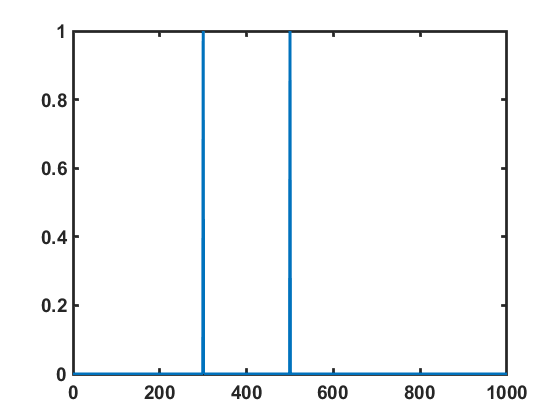

%SO lets say t is times from 1 to 10 seconds
%and we have can i fajipoa;klnfiunb mhnjupiidasd ji;ol njupi     

times=1:1000;
spikes=[300,500];

%so how Do i graph spikes over time?
%feels like logical indexing
%no i want inverse of logical indexing


didSpike=indexToBoolean(times,spikes);
plot(times,didSpike);

Jacob Smith Computational Neuroscience

Needs array of times and array of which indexes of the array where spikes

returns a didSpike boolean paced to times array for pacing

function didSpike=indexToBoolean (times, spikeIndexes)
%Converts an array of spike Indexes
%creates a blank boolean array of same length as time
didSpike=zeros(size(times));
%iterate through spikeIndex variable
for index=1:length(spikeIndexes)
    %get the next index that was a spike
    spikeIndex=spikeIndexes(index);
    %set the boolean array at that index to true
    didSpike(spikeIndex)=true;
end
return;
end